# STA_PendulumLIVE.mlx

This algorithm is designed to track the angular acceleration, angular velocity, and angular position of a pendulum as a function of time for three complete cycles.

## Define Parameters

iterations = 500;               % number of iterations in STA 
m = 0.2;                        % mass of object in motion [kg]
w0 = 0;                         % initial angular velocity
theta0 = 90;                    % mass 90 degrees from equilibrium
dt = 0.01;                      % step time inbetween point approximations
R = 0.4;                        % length of the lightweight rod 
g = 9.81;                       % acceleration due to gravity
T = (2*pi)*sqrt(R/g);           % period calculation
t = 0:((T*3)/iterations):(T*3); % time elapsed - 3 periods
w = ones(1,iterations);         % intiialize angular velocity vector
theta = ones(1,iterations);     % initialize angular position vector 
accelerate = ones(1,iterations);% initialize angular acceleration vector

## Calculations

w(1) = w0*w(1);                % set initial position
theta(1) = theta0*theta(1);    % set initial velocity
accelerate(1) = -g*sind(theta(1));

for i = (1:1:iterations)
    theta(i+1) = theta(i) + (w(i).*dt)+((1/2).*w(i));                        % Approximate position 
    w(i+1) = w(i) +((1/2).*((-g*sind(theta(i)))+(-g*sind(theta(i+1)))).*dt); % Approximate velocity
    accelerate(i+1) = -g*sind(theta(i+1));                                   % Approximate Acceleration
end

## Plotting

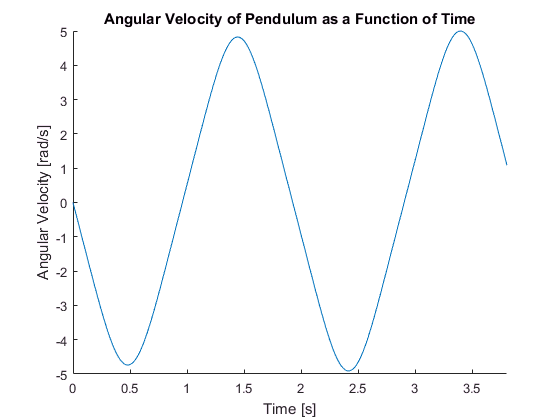

figure(1);                                                       % create first figure
hold on;

title('Angular Velocity of Pendulum as a Function of Time');     % Label title
ylabel('Angular Velocity [rad/s]');                              % Label y axis
xlabel('Time [s]');                                              % Label x axis'
xlim([0 (3*T)]);                                                 % set x axis limit

plot(t,w);                                                       % plot position vs time

hold off;

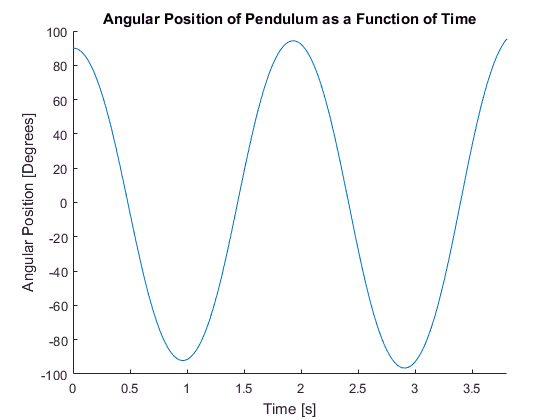


figure(2);                                                       % create second figure
hold on;

title('Angular Position of Pendulum as a Function of Time');     % Label title
ylabel('Angular Position [Degrees]');                            % Label y axis
xlabel('Time [s]');                                              % Label x axis
xlim([0 (3*T)]);                                                 % set x axis limit

plot(t,theta);                                                   % plot velocity vs time

hold off;

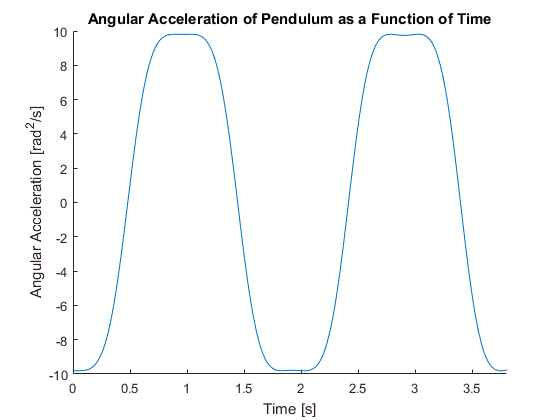


figure(3);                                                       % create third figure
hold on;

title('Angular Acceleration of Pendulum as a Function of Time'); % Label title
ylabel('Angular Acceleration [rad^2/s]');                        % Label y axis
xlabel('Time [s]');                                              % Label x axis
xlim([0 (3*T)]);                                                 % set x axis limit

plot(t,accelerate);                                              % plot velocity vs time

hold off;